# **ACM 11 Homework 1 (Spring 2023)**

## **Due Friday, April 7, 11:59pm Pacific Time, by upload to Canvas.**

This assignment is worth 100 points. The points in this file add up to 50 points - if your code completes the task correctly then you will receive the full 50 points for credit. An additional 10 points are allocated to readable code. A further 10 points are allocated to efficient code (unless explicitly instructed to write inefficient code). The final 30 points for the written answers to the questions in the code being clear, correct, and in complete sentences.

### Problem 1 (5 points)

Use the `disp` command to write a "Hello World" program in the following block.

disp("Hello World");

Hello World


### **Problem 2 (Fibonacci sequence, 10 points)**

The classical Fibonacci sequence of integers is defined via the following recursive relation:


$$F_{m+2} = F_{m+1}+F_{m} \  (m \geq 1), \ F_{1}=F_{2}=1$$


Write a script that uses a for loop to compute the first $$n = 20$$ terms $$\{F_{m}\}_{m=1}^{n}$$ in the Fibonacci sequence in the following block. Use the `zeros` command to pre-allocate a 20-by-1 array for all the terms of the sequence. Suppress the output within your for loop but display all computed elements at the end.

arr = zeros(20,1);
arr(1:2) = 1;
for i = 3:length(arr)
    arr(i) = arr(i-1) + arr(i-2);
end
disp(arr)

           1
           1
           2
           3
           5
           8
          13
          21
          34
          55
          89
         144
         233
         377
         610
         987
        1597
        2584
        4181
        6765



As a check of your work, the 20th Fibonacci number is 6765. Compare the 20th element of your Fibonacci array by subtracting it from the true answer -- the error should be 0:

6765 - arr(20)

ans = 0

### **Problem 3 (Pre-allocation, 15 points)**

Here we will use a toy example to illustrate how preallocation can help optimize your MATLAB code. In your later work, you should always try preallocating the maximum amount of space required for an array at first instead of continuously resizing the array.

Consider a sequence $$\{x_{k}\}_{k=1}^{\infty}$$ defined as follows:


$$$x_{k+1} = \frac{1}{2}(x_{k}^2-x_{k}+2), \ x_{1} = \frac{3}{2}$$$


We want to compute the first $$10^6$$ terms in this sequence and store them in a row vector.

**(5 points) **Initialize the final output as a scalar and append a new term to it in each round of the loop. Record the running time (Hint: try using "tic" and "toc" ) Please write your code in the following block:

tic 
x1 = 3/2;
for i = 2:100000 %cannot do 10^6 as matlab crashes
    xk = (x1(i-1)^2 - x1(i-1) + 2)/2;
    x1 = [x1, xk];
end
toc

Elapsed time is 2.491271 seconds.


**(5 points) **Initialize the final output as an array with the desired size and update one term in the array in each round of the loop. Please write your code in the following block:

tic 
xk = zeros(1000000,1);
xk(1) = 3/2;
for i = 2:100000
    xk(i) = (xk(i-1)^2 - xk(i-1) + 2)/2;
end
toc

Elapsed time is 0.008033 seconds.


**(5 points) **Compare the two running times you recorded above. Briefly discuss what you observed. (Please write your discussion in the string in the following block.)

disp(['The runtime is much faster for the preallocated array, as it does not need ' ...
    'to be resized each time an element is added.' ...
    '' ...
    ' This makes sense as the runtime of resizing an array is terrible ' ...
    'especially as the data set gest large, and we are not resizing by a scalar'])

The runtime is much faster for the preallocated array, as it does not need to be resized each time an element is added. This makes sense as the runtime of resizing an array is terrible especially as the data set gest large, and we are not resizing by a scalar


### **Problem 4 (Plotting a line, 10 points)**

We want to plot the line $y=m\;x+b$ for different values of $m$. In the following block, fix $b=2\ldotp 2$ and loop through 6 values of $m$ between 1 and 3, and plot y vs. x on the same axis for x in [0,1] in different colors using the hold command. Label your axes and give the plot a title. Include an appropriate legend.

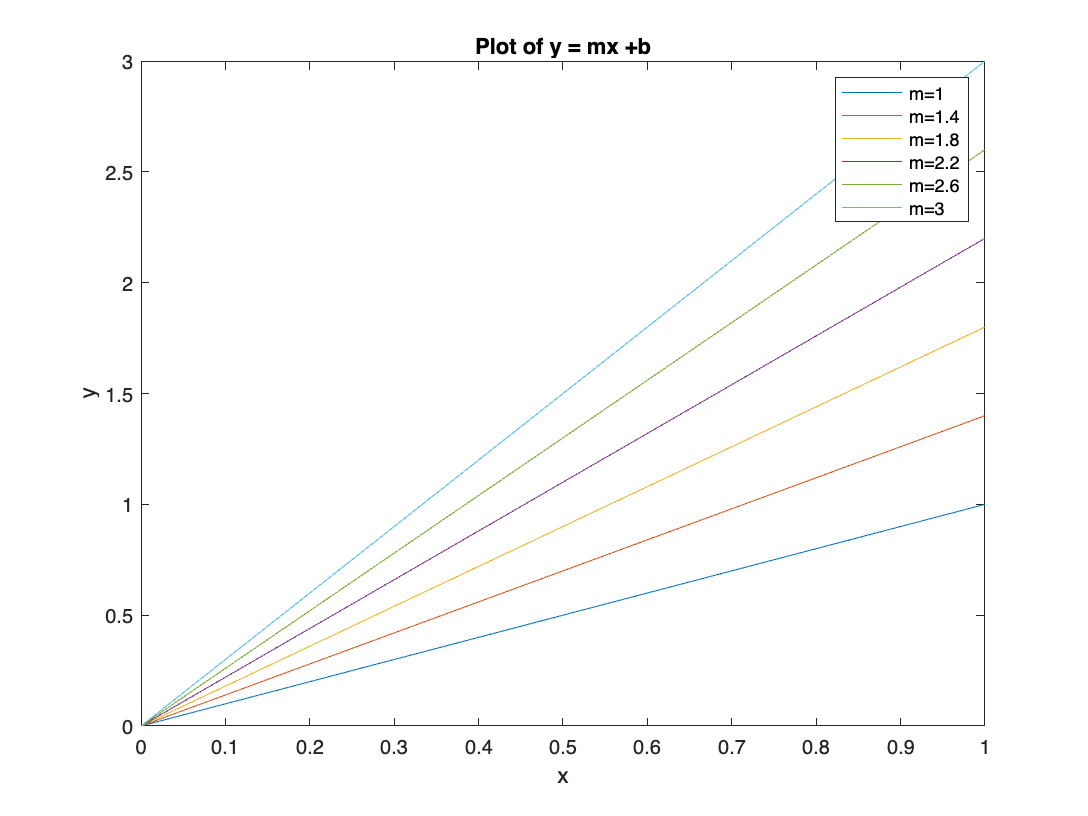

b = 2.2;
x = linspace(0,1); %x values will be constant

for m = linspace(1,3,6)
    y = x * m;
    plot(x,y);
    hold on;
end
xlabel('x');
ylabel('y');
title('Plot of y = mx +b');
legend({"m=1", "m=1.4", "m=1.8", "m=2.2", "m=2.6", "m=3"});
hold off

### **Problem 5 (Plotting a multivariate function, 10 points)**

We want to plot the function $z=m{\;}_1 x+m_2 y^2$ for (x,y) in [0,1]x[-0.5,0.5] (i.e. on the unit square). We will use $m_1 =2$ and $m_2 =3$. We will do this several ways. 

**(3 points) **First, define an array of x-values from 0 to 1  with 10 points, and an array of y-values from -0.5 to 0.5 with 15 points. Pre-allocate an 15x10 array for z, and **loop** through every combination of x- and y-values to fill in the z array. Use the tic/toc commands to time how long this takes. Then use the surf command to plot z vs. x and y. Label your axes. 

tic
m1 = 2;
m2 = 3;
x = linspace(0,1,10);
y = linspace(-0.5, 0.5, 15);
z = zeros(15,10);
for xidx = 1:10
    for yidx = 1:15
        z(yidx, xidx) = m1 * x(xidx) + m2 * (y(yidx))^2 ;
    end
end
toc

Elapsed time is 0.020438 seconds.


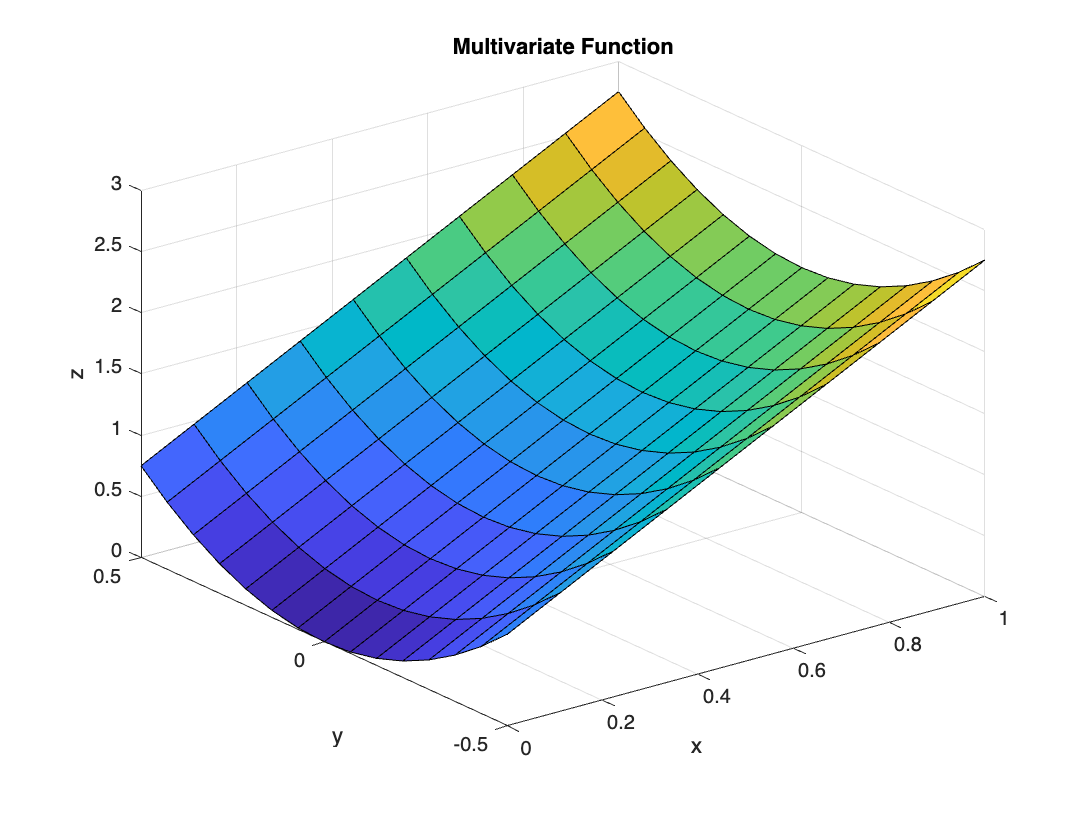

figure(2);
surf(x,y,z);
title('Multivariate Function');
xlabel('x');
ylabel('y');
zlabel('z');

**(4 points) **Now compute the values of the z-array for the above function above in one line, without using a loop. Use the tic/toc commands to time how long this takes. Use the surf command to plot z vs. x and y again. It should look identical to your above plot (otherwise you need to check your code!).

tic
x = linspace(0,1,10);
y = linspace(-0.5,0.5,15);
[X,Y] = meshgrid(x,y);
z = 2*X + 3*Y.^2;
toc

Elapsed time is 0.012823 seconds.


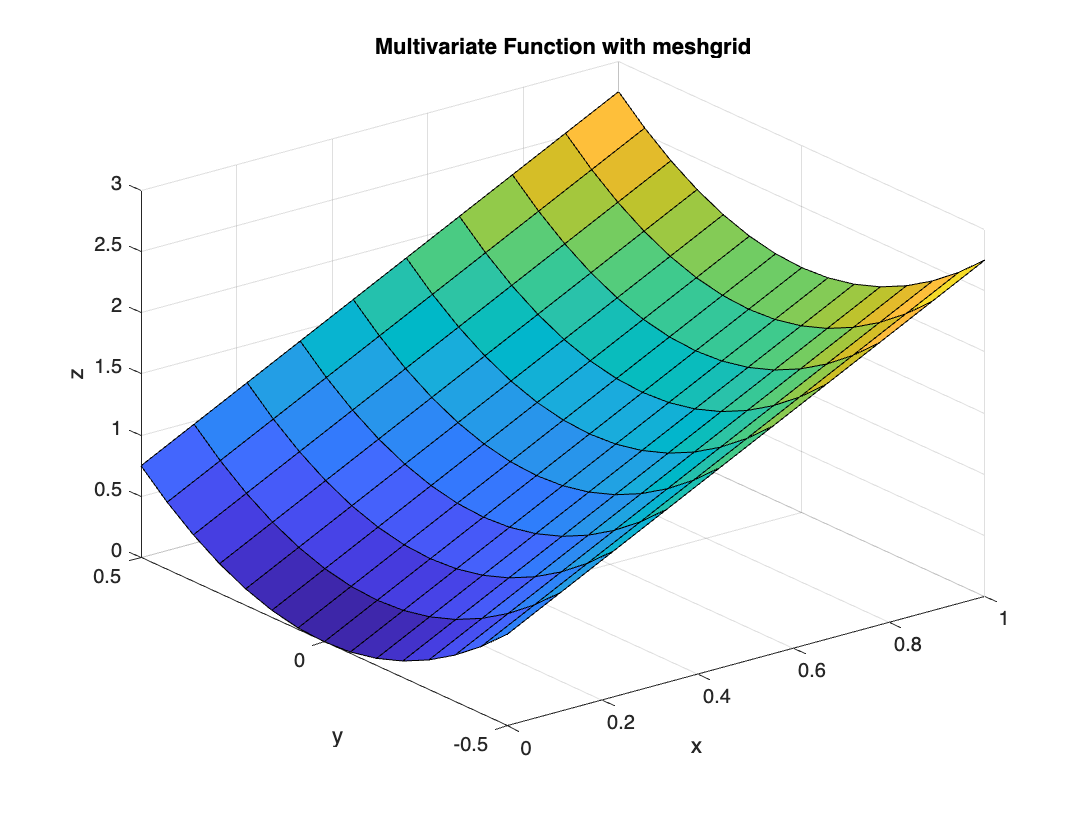

figure(3); clf
surf(x,y,z);
title('Multivariate Function with meshgrid');
xlabel('x');
ylabel('y');
zlabel('z');

**(3 points) **Finally, define an anonymous function f(x,y) to compute z as defined above, and use the built-in function` fsurf `to plot this function on the domain [0,1]x[-0.5,0.5]. How does this plot compare to your plots above? (Please write your discussion in the string in the following block.)

tic
f= @(X,Y) 2*X + 3*Y.^2;
figure(4); clf
fsurf(f, [0 1 -0.5 0.5]);
toc

Elapsed time is 0.923998 seconds.


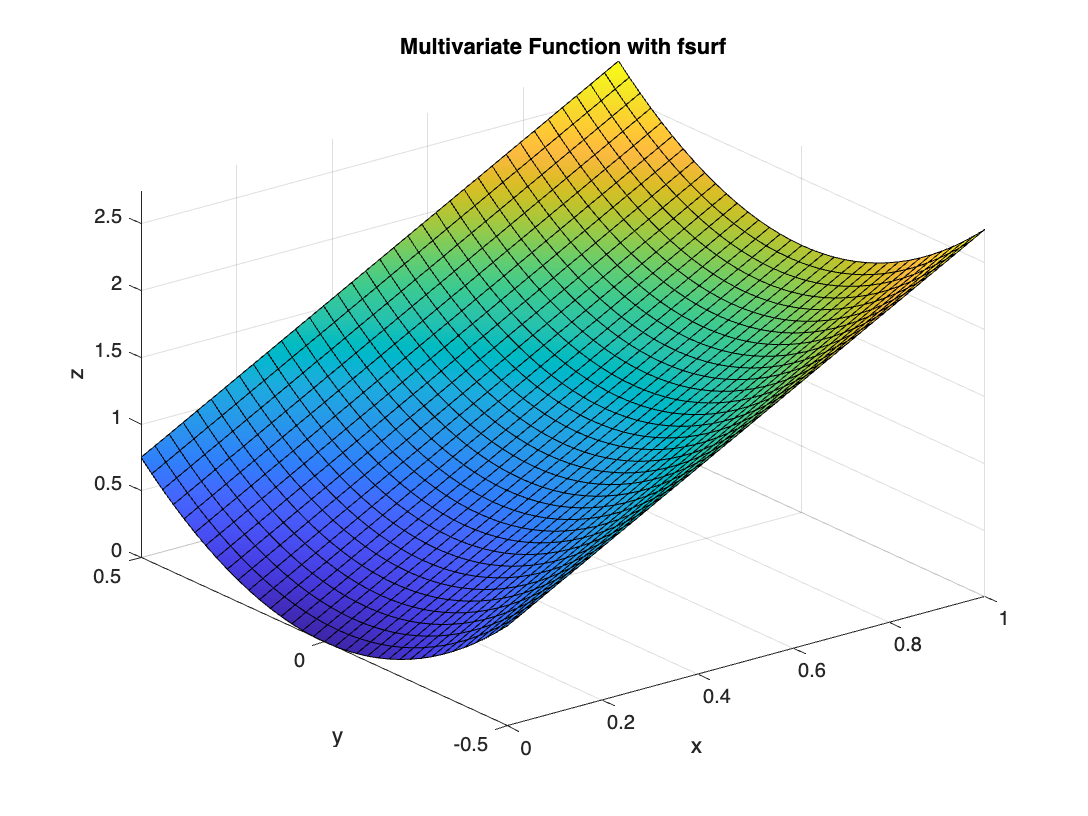

figure(4);
title('Multivariate Function with fsurf');
xlabel('x');
ylabel('y');
zlabel('z');

disp('The runtime is much slower, but at a result we have far more points and the plot looks much smoother and cleaner')

The runtime is much slower, but at a result we have far more points and the plot looks much smoother and cleaner
